## 一、

### （1）

num=1;
den=[1 1];
figure(1);
[z p k]=tf2zp(num,den)


z =

  空的 0×1 double 列向量



p = -1

k = 1

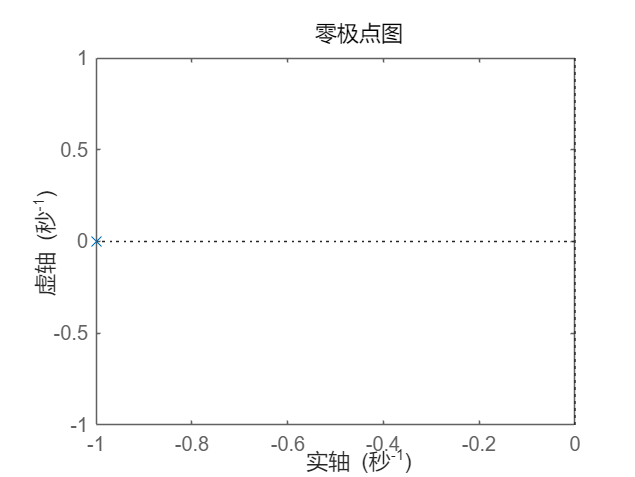

pzmap(tf(num,den));

### (2)

num=[10,10];
den=[1,0];
figure(2);
[z p k]=tf2zp(num,den)

z = -1

p = 0

k = 10

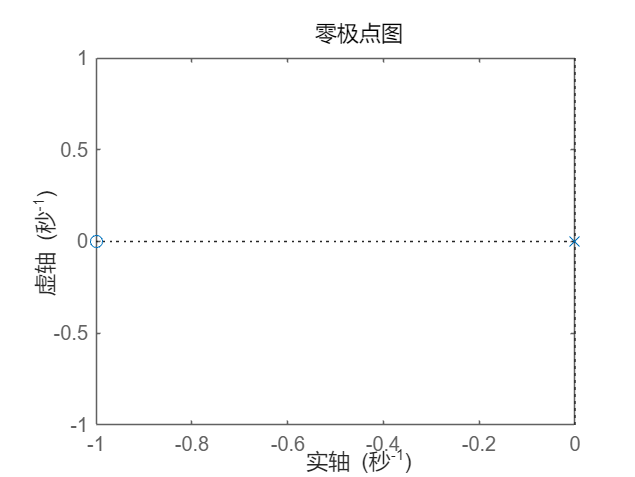

pzmap(tf(num,den));

### (3)

num=10;
den=[1,-5,0];
figure(3);
[z p k]=tf2zp(num,den)


z =

  空的 0×1 double 列向量



p =      0
     5


k = 10

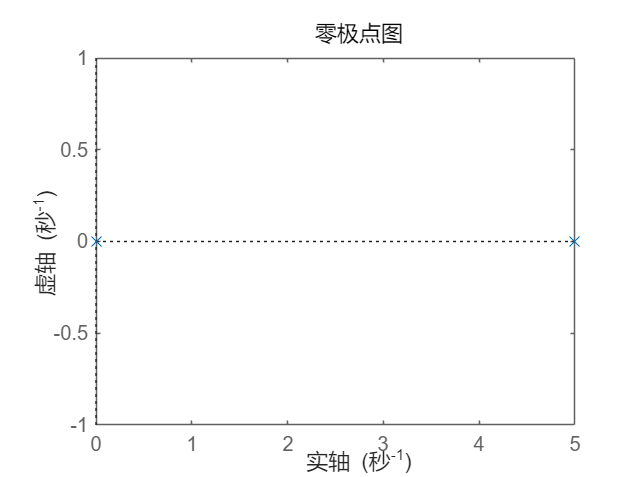

pzmap(tf(num,den));

二、

（1）

z=[1,2].'

z =      1
     2


p=[-1,-2].'

p =     -1
    -2


k=3

k = 3

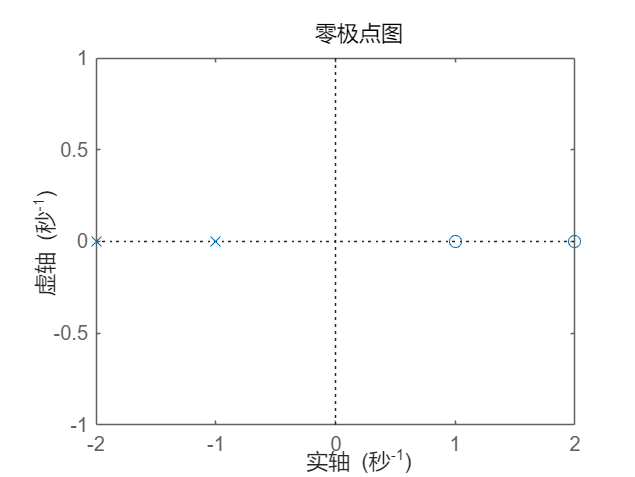

pzmap(zpk(z,p,k));

(2)

num=1;
den=[1,0];
[z p k]=tf2zp(num,den)


z =

  空的 0×1 double 列向量



p = 0

k = 1

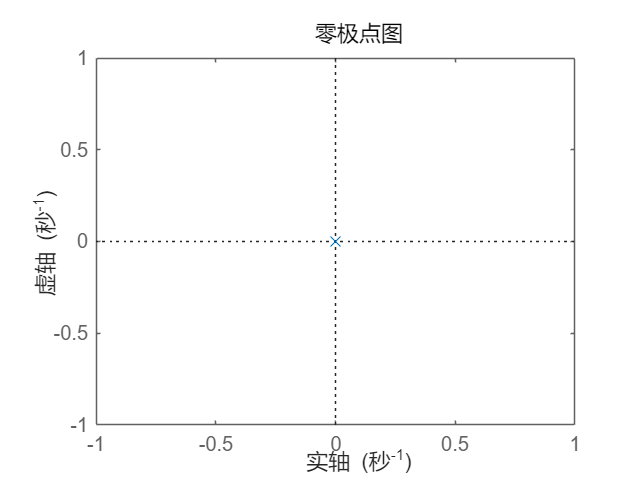

pzmap(tf(num,den));

(3)

num=0.6*[3,2,2,5];
den=[1,3,2,1];
[z p k]=tf2zp(num,den)

z =   -1.2284 + 0.0000i
   0.2809 + 1.1304i
   0.2809 - 1.1304i


p =   -2.3247 + 0.0000i
  -0.3376 + 0.5623i
  -0.3376 - 0.5623i


k = 1.8000

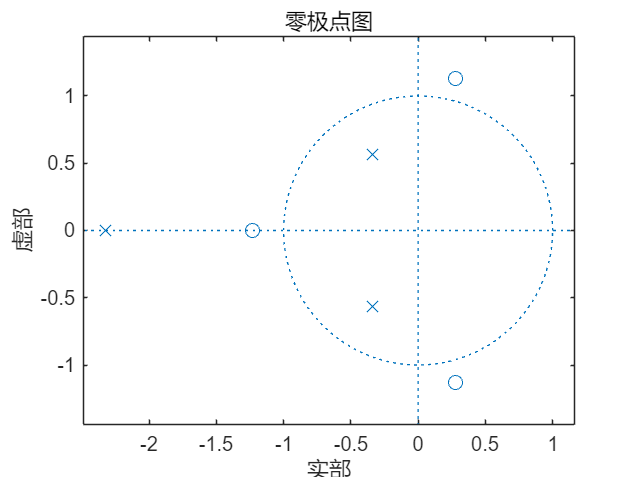

zplane(num,den);

三、

(1)

A=[2,2,1;1,3,1;1,2,2];
B=[3;3;4];
C=[1,1,1];
D=0;
[z p k]=ss2zp(A,B,C,D)

z =     1.1000
    1.0000


p =     5.0000
    1.0000
    1.0000


k = 10

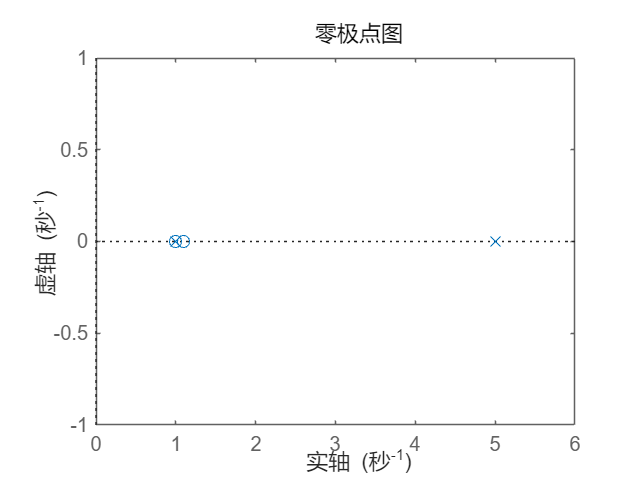

pzmap(zpk(z,p,k));

%Y轴右侧有极点，系统不稳定

(2)

z=-3

z = -3

p=[-1,-5,-15].'

p =     -1
    -5
   -15


k=15

k = 15

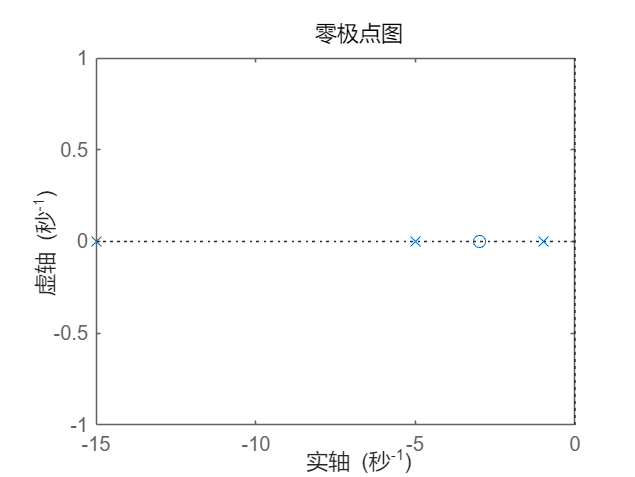

pzmap(zpk(z,p,k));

%极点都位于y轴左侧，系统稳定

(3)

num=conv([1,-1.414,1],[1,1]);
den=conv([1,0.9,0.81],[1,-0.3]);
[z,p,k]=tf2zp(num,den)

z =   -1.0000 + 0.0000i
   0.7070 + 0.7072i
   0.7070 - 0.7072i


p =   -0.4500 + 0.7794i
  -0.4500 - 0.7794i
   0.3000 + 0.0000i


k = 1

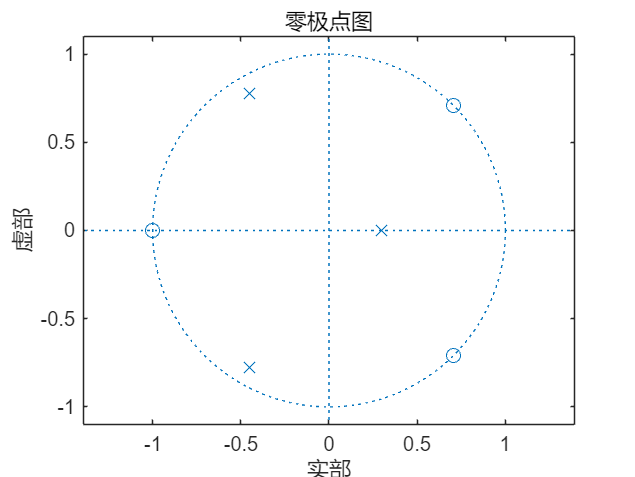

zplane(num,den);

%极点均位于单位圆内，故系统稳定

四、

（1）

a = [1,5,8,10];
N = length(a);
M = ceil(N/2);
R = zeros(N, M);
R(1,:)= [a(1:2:end) zeros(1,M-length(a(1:2:end)))];
R(2,:)= [a(2:2:end) zeros(1, M - length(a(2:2:end)))];
for n = 3:N
    if R(n-1,1)==0
        R(n-1,1)=eps
    end
    for m = 1:M-1
        R(n, m) = (R(n-2, m+1) * R(n-1, 1) - R(n-2, 1) * R(n-1, m+1)) / R(n-1, 1);
    end
end
disp('Routh阵列：');

Routh阵列：


disp(R);

     1     8
     5    10
     6     0
    10     0



if all(R(:,1) > 0)
    disp('系统稳定');
else
    disp('系统不稳定');
end

系统稳定


(2)

a = [1,1,6,8,1];
N = length(a);
M = ceil(N/2);
R = zeros(N, M);
R(1,:)= [a(1:2:end) zeros(1,M-length(a(1:2:end)))];
R(2,:)= [a(2:2:end) zeros(1, M - length(a(2:2:end)))];
for n = 3:N
    if R(n-1,1)==0
        R(n-1,1)=eps
    end
    for m = 1:M-1
        R(n, m) = (R(n-2, m+1) * R(n-1, 1) - R(n-2, 1) * R(n-1, m+1)) / R(n-1, 1);
    end
end
disp('Routh阵列：');

Routh阵列：


disp(R);

    1.0000    6.0000    1.0000
    1.0000    8.0000         0
   -2.0000    1.0000         0
    8.5000         0         0
    1.0000         0         0



if all(R(:,1) > 0)
    disp('系统稳定');
else
    disp('系统不稳定');
end

系统不稳定


(3)

a = [1,1,2,2,3];
N = length(a);
M = ceil(N/2);
R = zeros(N, M);
R(1,:)= [a(1:2:end) zeros(1,M-length(a(1:2:end)))];
R(2,:)= [a(2:2:end) zeros(1, M - length(a(2:2:end)))];
for n = 3:N
    if R(n-1,1)==0
        R(n-1,1)=eps;
    end
    for m = 1:M-1
        R(n, m) = (R(n-2, m+1) * R(n-1, 1) - R(n-2, 1) * R(n-1, m+1)) / R(n-1, 1);
    end
end
disp('Routh阵列：');

Routh阵列：


disp(R);

   1.0e+16 *

    0.0000    0.0000    0.0000
    0.0000    0.0000         0
    0.0000    0.0000         0
   -1.3511         0         0
    0.0000         0         0



if all(R(:,1) > 0)
    disp('系统稳定');
else
    disp('系统不稳定');
end

系统不稳定
